# Aula 7 - Laboratório de Controle - 2021/1 

## Modelagem do motor CC e sintonia de controladores

## Nome: Arthur Lorencini Bergamaschi

turma=2;
I=1;
Tempo=4;

M=[5 9 3 4 1 2 12 7 11 10 8 6
     2 4 5 11 10 1 9 8 7 3 6 12
     9 1 12 8 5 11 6 3 2 4 10 7
     7 6 9 2 11 5 8 4 3 10 12 1
    12 9 3 11 7 8 5 2 10 1 6 4]';
M=M*fliplr(eye(5,5));
I=M(I,turma);
load dados.mat
i=I*50;
ind=(i-20):(i+35);
y1=y1(ind);
u1=u1(ind);
t1=t1(ind);
Ref=mean(y1(end-10:end));
u0=mean(u1(1:10));
arquivo='motor_cc_R2018.slx';

## Atividade 1 - Análise dos dados do motor CC

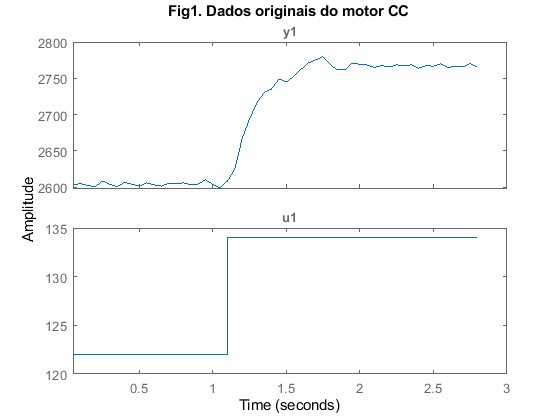

dat=iddata(y1,u1,Ts);
figure; plot(dat);title('Fig1. Dados originais do motor CC');

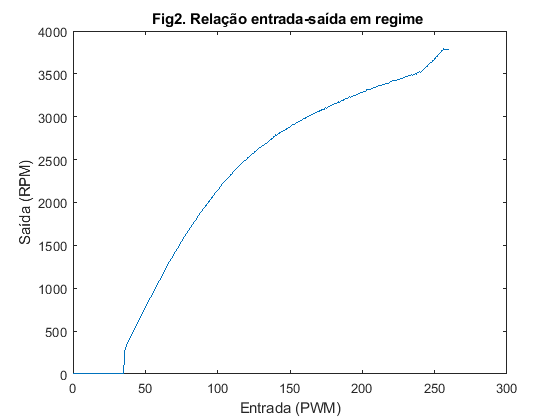

figure;plot(u2,y2);title('Fig2. Relação entrada-saída em regime ')
xlabel('Entrada (PWM)');ylabel('Saída (RPM)');

1.1 Explique o sinal aplicado e sua resposta usando a Figura 1.

O sinal aplicado, conforme a figura 1, é a de um degrau que começou em 122 e foi para 134. Provavelmente o degrau começou nesse valor para poder vencer a zona morta do motor cc.

A saída é a respota do motor CC a essa entrada degrau, veja que ele contém ruídos e uma demora visível para atingir o valor de regime.

1.2 O que é zona morta e qual seu valor no motor utilizado? (Figura 2)

Zona morta é a região em que o motor precisa de um certo valor de entrada a mais para que ele comece a girar por causa dos seus atritos internos.

1.3 Calcule aproximadamente o ganho do motor para rotação de 1000rpm e para a rotação de regime da figura 1 

O ganho para a rotação de 1000rpm é de 1004-923/57-54 = 27

Para a rotação de regime, o ganho é de 2808-2778/143-140 = 9.66

## Atividade 2 - Obtenção do modelo do motor CC

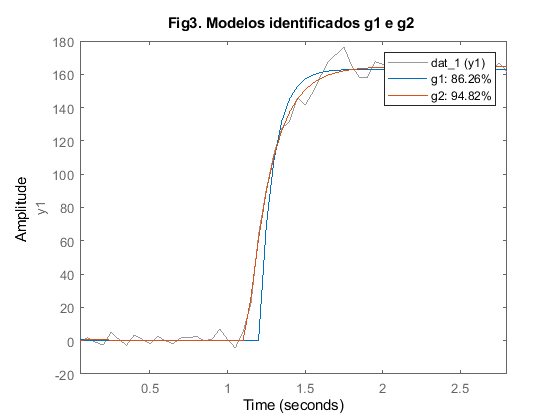

delay=0.1;
dat_1=iddata(y1-y1(1),u1-u1(1),Ts);
g1=tfest(dat_1,1,0,delay);
g2=tfest(dat_1,2,0);
figure;compare(dat_1,g1,g2);title('Fig3. Modelos identificados g1 e g2 ');


g1=tf(g1.Numerator/g1.Denominator(2),g1.Denominator/g1.Denominator(2),'InputDelay',g1.IODelay)

g1 =
 
                    13.59
  exp(-0.1*s) * -------------
                0.09036 s + 1
 
Continuous-time transfer function.



g2=tf(g2.Numerator,g2.Denominator)

g2 =
 
          3118
  ---------------------
  s^2 + 40.55 s + 227.1
 
Continuous-time transfer function.



K=freqresp(g2,0)

K = 13.7249

s0=stepinfo(g2)

s0 = struct with fields:
        RiseTime: 0.3384
    SettlingTime: 0.6157
     SettlingMin: 12.3744
     SettlingMax: 13.7133
       Overshoot: 0
      Undershoot: 0
            Peak: 13.7133
        PeakTime: 1.0861


2.1 Use os dados de dat_1 e obtenha um modelo g1 de ordem 1+delay e g2 de ordem 2, escolhendo um delay que dê um bom fit para g1. Compare o fit de g1 e g2.

Comparando o fit de g1 e g2, vemos que o fit de g1 é de 86% e o de g2 é de 95%. Vemos que o modelo de segunda ordem sem delay tem um fit melhor e o fit do g1 é aceitável.

2.2 Compare o ganho K obtido via g2 e o ganho K que calculou na atividade 1.3

O valor de K via matlab foi de 13. O ganho K calculado na atividade foi de 27 para a rotação de 1000rpm e 9.66 para a rotação em regime. O ganho K via matlab está dentro da faixa dos ganhos calculados para os dois pontos.

2.3 Qual o tempo de estabelecimento deste sistema e qual a constante de tempo comparando a Figura a e a Figura 3?

O a constante de tempo é cerca de 0.15s , enquanto o de estabelecimento é de 0.61s. Vemos que o valor do tempo de estabelecimento é próximo a 4 vezes a constante de tempo.

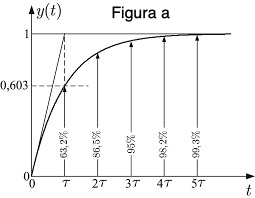 

## Atividade 3 - Projeto de um controlador PID via sintonia lambda

A Tabela abaixo mostra a sintonia $\lambda$ para controladores PI ou PID usando modelo de primeira ordem+tempo morto

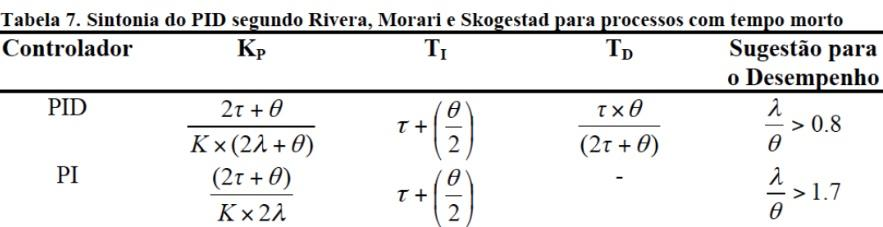

3.1 Sintonize os parâmetros de um controlador PI via metodo $\lambda$ de modo que o tempo de estabelecimento seja ser menor que o de malha aberta e $UP\leq5\%$ usando g1 para o projeto. Escolha $\lambda$ usando como referência a constante de tempo da atividade 2.2.

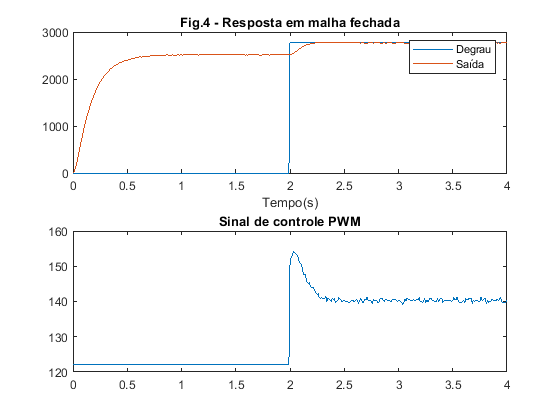

lambda=0.09;
C=sintonia(g1,'PI','lam',lambda);

N=100;
kp=C.Kp;ki=C.Ki;kd=C.Kd;
Ts=0.01;
[Y,t]=simula_slx(arquivo,Tempo);

[erro,UP,SettlingTime, iae,G2] = desempenho(Y(:,[1,3]),t,Ref,2);
str = sprintf('ts(ma) = %.2f ts(mf) = %.2f  UP = %.1f  IAE = %.0f',s0.SettlingTime, SettlingTime,UP,iae);

figure;
subplot(2,1,1);plot(t,Y(:,[1,3]));legend('Degrau','Saída');xlabel('Tempo(s)');title('Fig.4 - Resposta em malha fechada');shg
subplot(2,1,2);plot(t,Y(:,2));title('Sinal de controle PWM');

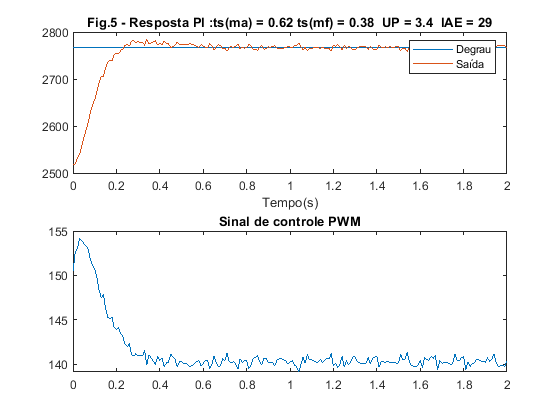


figure;
t1=sum(t<2)+1;
subplot(2,1,1);plot(t(t1:end)-2,Y(t1:end,[1,3]));legend('Degrau','Saída');xlabel('Tempo(s)');title(strcat('Fig.5 - Resposta PI : ',str));
subplot(2,1,2);plot(t(t1:end)-2,Y(t1:end,2));title('Sinal de controle PWM')

erro3=erro;
UP3=UP;
SettlingTime3=SettlingTime;
iae3=iae;

3.2 Sintonize os parametros de um controlador PID via metodo $\lambda$ de modo que o tempo de estabelecimento seja ser menor que o de malha aberta e $UP\leq5\%$ usando g1 para o projeto. 

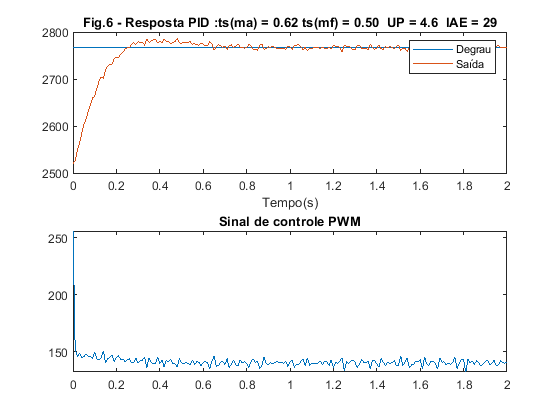

lambda=0.03;
C=sintonia(g1,'PID','lam',lambda);
kp=C.Kp;ki=C.Ki;kd=C.Kd;
[Y,t]=simula_slx(arquivo,Tempo);
[erro,UP,SettlingTime, iae] = desempenho(Y(:,[1,3]),t,Ref,2);
str = sprintf('ts(ma) = %.2f ts(mf) = %.2f  UP = %.1f  IAE = %.0f',s0.SettlingTime, SettlingTime,UP,iae);
figure;
t1=sum(t<2)+1;
subplot(2,1,1);plot(t(t1:end)-2,Y(t1:end,[1,3]));legend('Degrau','Saída');xlabel('Tempo(s)');title(strcat('Fig.6 - Resposta PID : ',str));
subplot(2,1,2);plot(t(t1:end)-2,Y(t1:end,2));title('Sinal de controle PWM')


erro3(2,1)=erro;
UP3(2,1)=UP;
SettlingTime3(2,1)=SettlingTime;
iae3(2,1)=iae;

A tabela abaixo mostra a sintonia de um controlador PID para um modelo de ordem 2 com polos complexos ou reais)

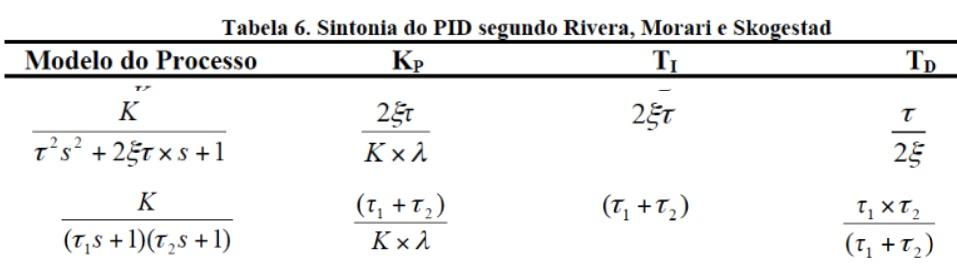

3.3 Sintonize os parametros de um controlador PID via metodo $\lambda$ de modo que o tempo de estabelecimento seja ser menor que o de malha aberta e $UP\leq5\%$ usando g2 para o projeto. 

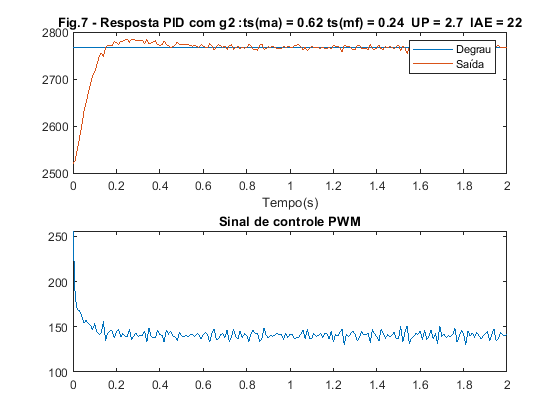

lambda=0.05;
C=sintonia(g2,[],'ordem2',lambda);
kp=C.Kp;ki=C.Ki;kd=C.Kd;
[Y,t]=simula_slx(arquivo,Tempo);
[erro,UP,SettlingTime, iae] = desempenho(Y(:,[1,3]),t,Ref,2);
str = sprintf('ts(ma) = %.2f ts(mf) = %.2f  UP = %.1f  IAE = %.0f',s0.SettlingTime, SettlingTime,UP,iae);
figure;
t1=sum(t<2)+1;
subplot(2,1,1);plot(t(t1:end)-2,Y(t1:end,[1,3]));legend('Degrau','Saída');xlabel('Tempo(s)');title(strcat('Fig.7 - Resposta PID com g2 : ',str));
subplot(2,1,2);plot(t(t1:end)-2,Y(t1:end,2));title('Sinal de controle PWM')


erro3(3)=erro;erro=erro3;
UP3(3)=UP;UP=UP3;
SettlingTime3(3)=SettlingTime;SettlingTime=SettlingTime3;
iae3(3)=iae; iae=iae3;
Metodos={'PI_g1';'PID_g1';'PID_g2'};
Tabela1=table(Metodos,erro,UP,SettlingTime,iae)

Tabela1 = 3×5 table
     Metodos        erro        UP      SettlingTime     iae  
    __________    ________    ______    ____________    ______

    {'PI_g1' }    0.026246    3.3932      0.38227       28.777
    {'PID_g1'}    0.012801    4.5546      0.50154       28.644
    {'PID_g2'}    0.019523     2.714      0.24431       21.559


3.4 Comente os valores de $\lambda$ usados nas 3 sintonias, justificando as escolhas. 

Para o primeiro caso, partiu-se do lambda igual a 0.14s e foi diminuindo até chegar num valor em que o UP fosse < 5% e o tempo de estabelecimento de malha fechada fosse menor do que o de malha aberta. Chegou-se em um valor satisfatório de 0.09 para que tivesse as condições satisfeitas.

Para as outras escolhas, partiu-se do mesmo procedimento anterior. O valor para o segundo caso foi de 0.03 e para o terceiro caso foi de 0.05

3.5 Qual o melhor controlador usando como critério o IAE e como critério UP e a tempo de estabelecimento?

Para os três critérios, ao analisar a tabela1, o melhor é o PID_g2, pois ele possui os menores valores de IAE (21.5), UP (2.7%) e tempo de estabelecimento (0.24s), pois ele sobe rápido sem dar um tranco maior do que os outros.

## Atividade 4 - Especificação de um modelo de referência no tempo

4.1 A partir do tempo de estabelecimento $t_s$ e da sobreelevação $UP$ obtidos com os controladores projetados, especifique um protótipo de segunda ordem $G(s)=\frac{w_n^2}{s(s+2\zeta w_n)}$ tal que sua resposta ao degrau em malha fechada de $M(s)=\frac{G(s)}{1+G(s)}$ seja semelhante à que foi obtida. Compare a resposta de $M(s)$ com a dos controladores sintonizados. 

Vê-se que o modelo de malha fechada possui uma sobrelevação quase nula em comparação com o controlador sintonizado e além disso, um tempo de estabelecimento menor (cerca de 0.2s).

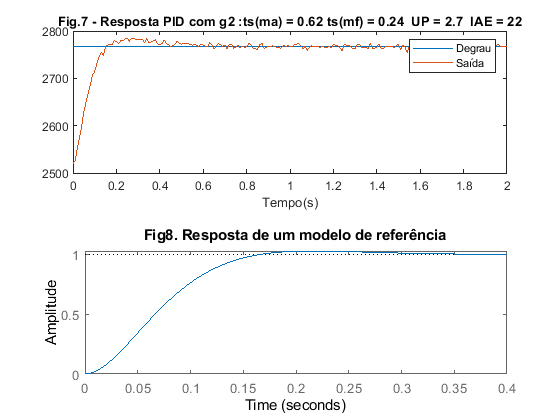

UP=2.71;
ts=0.24;
a=log(UP/100);
zeta=sqrt(a^2/(pi^2+a^2));
wn=4/(ts*zeta);
m=tf(wn^2,[1 2*zeta*wn wn^2]);
step(m);title('Fig8. Resposta de um modelo de referência');


datetime('now')

ans = datetime
   28-Jul-2021 21:12:18


pwd

ans = 'C:\Users\malaquias\Desktop\UFES\UFES-LCA\Aula7'